## Problem

100 ants are randomly placed in a square boxwith each side as1m.They move with an average speed of 1cm/s. If the ants collide with each other, they reverse their directions and start moving with the same speed. If ants reach the boundary, apply the periodic condition (i.e the ants will enter the squarefrom the opposite side). Perform the simulations until each ant at least collides once with the other ant. The objective of the study is to obtain the average distance between the ants before they collide with one another

## Assumptions

- each ant is a circle finite radius, say 5 mm => min 10 mm should be kept between each ants to avoid collision

- each ant moves one at a time such that other ant stay still but after collision , collided ants reverse direction and then position of all ants get reset to initial. similarly iterated for all other non collided ants

## Algorithm

- create position matrix of 100 ants by randomly assigning values between 0 to 1000mm (two 1D arrays for both x and y directions). convert to complex no.

- similary create velocity matrix 

- assign size of ant because points cannot collide except perfectly head on collition which is rare since no. of ants are less

- find position vectors of all ants w.r.t  i th ant by subtracting position vector of i th ant form all other ant position vector, 

- find displacement of i th ant.

- ant crossing happen when displacement vector of i th ant greater than position vector of all other ant w.r.t  i th ant (i.e available  distance is less compared to next displacement), also there is tolerance of 2* radius of ant 

- if crossing change direction of velocity vector of that ant 

- otherwise add to new position of ant

- check for periodic condition and apply correction if needed

- add a counter to add distance travelled by each ant before collision

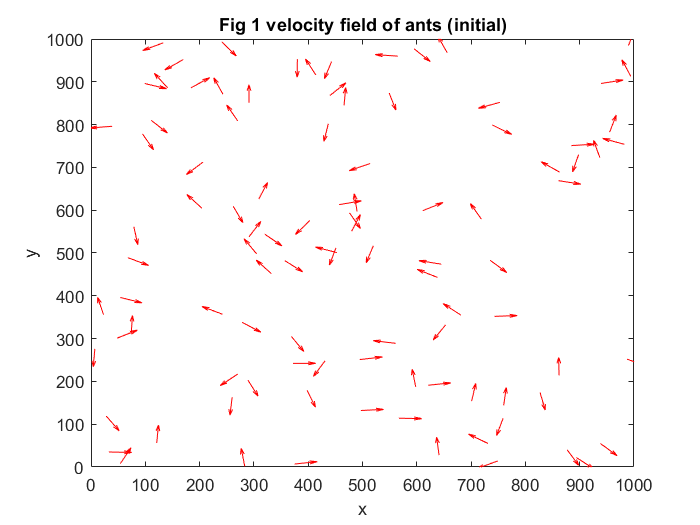

n = input('size of ant (assuming a circle - 0.5 to 10 mm)');
pos_x = randi(1000,[1 100]);
pos_y = randi(1000,[1 100]);
pos = (pos_x + 1i*pos_y); % using complex no. for easy calculation
save_pos = pos; % to reset positions
theta = rand([1 100])*2*pi -pi;
velocity =cos(theta) + 1i*sin(theta);

%plot(pos,'o')
%compass(real(velocity),imag(velocity))
quiver(real(pos),imag(pos),real(velocity),imag(velocity),.3,'r')
ylim([0 1000])
xlim([0 1000])
title('Fig 1 velocity field of ants (initial)')
xlabel('x')
ylabel('y')


dis = velocity*1; % t = 1 sec
counter = 0; % to counts the no. of collitions taken by each ant
collide = zeros([1 100]); % collition matrix for each itration (dynamic)
Not_collided = find(counter==0);
distance = zeros([1 100]);
while (~isempty(Not_collided)) % run untill there is no element in Non_collided matrix
    v = Not_collided(1); % take position of first element in non_collided matrix
    flag = 0; % to exit second loop
    while(flag ~= 1)
        change_pos = pos - pos(v); % avilable displacement betwwen vth and all other ants (w.r.t vth ant)
        collide = abs(change_pos - dis(v)) < 2*n; % crossing happen when available distance between v th ant compare to others is less than next displacement (also there is a verialbe tolerance of 2*n, where n is size of ant)
        collide(v) = false; % correction because above code always give this as true
        collide_pos = find(collide); % find position of collition if exist
        
        if collide_pos  % run iff collition matrix has value
            collide(v) = true;
            counter = counter + double(collide); % add to counter, this helps to keep track of no. of collision for each ant
            pos = save_pos; % reset ant position after collision for next itration
            velocity(collide) = -1*velocity(collide); % but direction is changed
            dis = velocity*1; % t = 1 sec
            flag = 1;
            
        elseif isempty(collide_pos) % runs if no collision
            pos(v) = pos(v) + dis(v); % find the next position of v th ant
            distance(v) = distance(v) + abs(dis(v)); % add distances
            
            %following codes are to check periodcity and to correct it
            pos_x = real(pos(v));
            pos_y = imag(pos(v));
            if pos_x > 1000
                pos_x = pos_x - 1000;
            end
            if pos_x < 0
                pos_x = pos_x + 1000;
            end
            if pos_y > 1000
                pos_y =pos_y - 1000;
            end
            if pos_y < 0
                pos_y = pos_y + 1000;
            end
            pos(v) = pos_x + 1i*pos_y;
            
        else
            disp(['error'])
            break
        end
        
    end
    Not_collided = find(counter==0);
end
avg_distance = mean(distance);
disp(['avg distance travelled = ',num2str(avg_distance),' mm'])

avg distance travelled = 361.15 mm


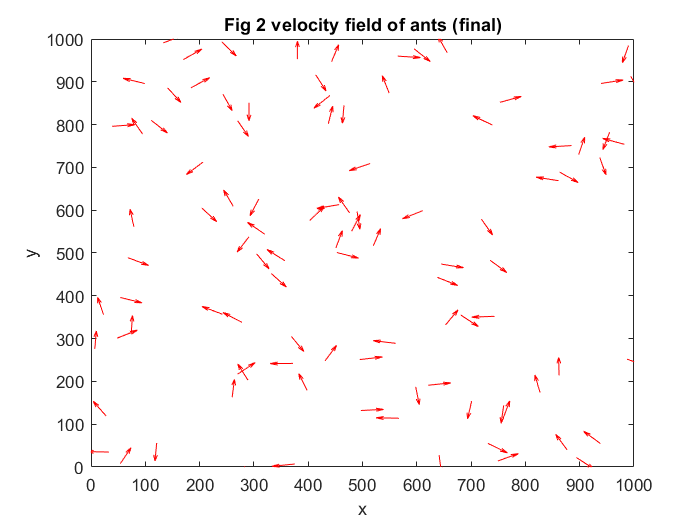


quiver(real(pos),imag(pos),real(velocity),imag(velocity),.3,'r')
ylim([0 1000])
xlim([0 1000])
title('Fig 2 velocity field of ants (final)')
xlabel('x')
ylabel('y')